[y, Fs] = audioread('Bill Conti - Rocky Theme.mp3');


avg = mean(y(:, 1));
avg10 = trimmean(y(:, 1), 90);
avg30 = trimmean(y(:, 1), 70);
avg50 = trimmean(y(:, 1), 50);


hold on;
l = length(y(:, 1));

l = 7356144

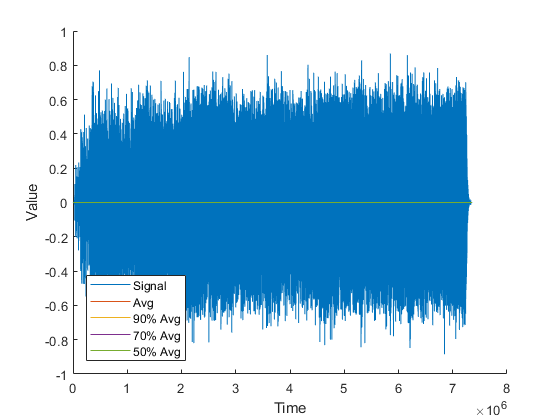

plot(y(:, 1));
plot(repelem(avg, l));
plot(repelem(avg10, l));
plot(repelem(avg30, l));
plot(repelem(avg50, l));

xlabel('Time')
ylabel('Value')
legend('Signal', 'Avg', '90% Avg', '70% Avg', '50% Avg', 'Location', 'southwest')
hold off;